clear;clc;

% load parameters
par_scg = importdata('par_scg_clock.txt');
par_scg = par_scg.data;

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_clock+7, 1);
y0(n_clock+1) = 1;
y0(n_clock+4) = 0;

tmax = 1000;
tspan = 0:0.1:tmax;

y = zeros(length(tspan), n_clock+7, 4);
t_V_17 = 523; % from paper CT17 is the acrophase of Bmal1
t_V_6 = 512;
t_V_0 = 506;
t_V_12 = 518;

[~, y(:, :, 1)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_0);
[~, y(:, :, 2)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y(:, :, 3)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_12);
[~, y(:, :, 4)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
y = real(y);

[~, y_ko] = ode15s(@ODE_SCG_CLOCK_KO, tspan, y0, [], par_clock, par_scg, t_V_17);
y_ko = real(y_ko);

% Smaller amplitude
y_sa = zeros(length(tspan), n_clock+7, 4);
vmax_bmal = par_clock(17);
par_clock(17) = 0.2;

[~, y_sa(:, :, 1)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_0);
[~, y_sa(:, :, 2)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y_sa(:, :, 3)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_12);
[~, y_sa(:, :, 4)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
y_sa = real(y_sa);

par_clock(17) = vmax_bmal;

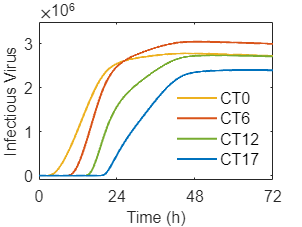

t_V = [t_V_0, t_V_6, t_V_12, t_V_17];
% color2 = [254 129 125; 129 184 223] ./ 255;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
% Plot virus 
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:4
    plot(tspan, y(:, n_clock+4, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
% scatter([48 48], [4400000 1900000]);
xlim([506 578]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
ylim([-1e5 3.5e6]);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('Infectious Virus','Fontsize',12, 'FontName', 'Arial');
% legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'southeast','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

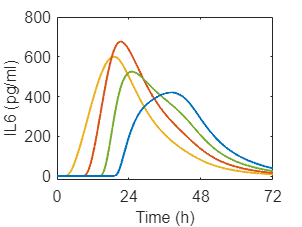

% Plot cytokines IL6
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:4
    plot(tspan, y(:, n_clock+5, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-20 800]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
% legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
% legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

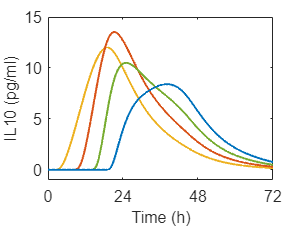

% Plot cytokines IL10
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:4
    plot(tspan, y(:, n_clock+7, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-1 15]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL10 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
% legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

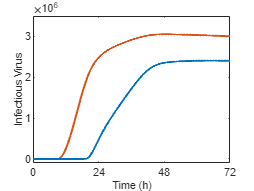

t_V = [t_V_0, t_V_6, t_V_12, t_V_17];
% color2 = [254 129 125; 129 184 223] ./ 255;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
% Plot virus 
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
for i = [2 4]
    plot(tspan, y(:, n_clock+4, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
% scatter([48 48], [4400000 1900000]);
xlim([506 578]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
ylim([-1e5 3.5e6]);
yticks([0 1e6 2e6 3e6]);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('Infectious Virus','Fontsize',8, 'FontName', 'Arial');
% legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',8, 'FontName', 'Arial');
% legend('CT6', 'CT17', 'Box', 'off', 'Location', 'southeast','Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

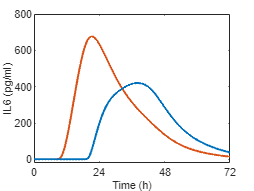


% Plot cytokines IL6
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
for i = [2 4]
    plot(tspan, y(:, n_clock+5, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-20 800]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',8, 'FontName', 'Arial');
% legend('CT6', 'CT17', 'Box', 'off', 'Location', 'northeast','Fontsize',8, 'FontName', 'Arial');
% legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

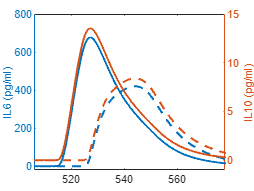


% Plot cytokines IL6
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
yyaxis left;
for i = [2 4]
    plot(tspan, y(:, n_clock+5, i), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-20 800]);
ylabel('IL6 (pg/ml)','Fontsize',8, 'FontName', 'Arial');

yyaxis right;
for i = [2 4]
    plot(tspan, y(:, n_clock+7, i), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-1 15]);
% legend('IL6-CT6', 'IL6-CT7', 'IL10-CT6','IL10-CT17');
ylabel('IL10 (pg/ml)','Fontsize',8, 'FontName', 'Arial');
hold off;

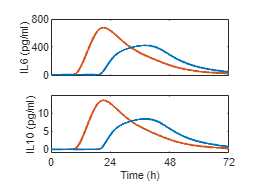


% Plot cytokines IL10
figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
for i = [2 4]
    plot(tspan, y(:, n_clock+5, i), '-', 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-20 800]);
xticks(506:24:578);
xticklabels({});
yticks([0 400 800]);
ylabel('IL6 (pg/ml)','Fontsize',8, 'FontName', 'Arial');

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
for i = [2 4]
    plot(tspan, y(:, n_clock+7, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-1 15]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
yticks([0 5 10])
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('IL10 (pg/ml)','Fontsize',8, 'FontName', 'Arial');
% legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

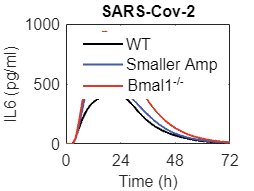

% Plot cytokines of clock KO
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
plot(tspan, y(:, n_clock+5, 4), 'k', 'LineWidth', 1.5);
plot(tspan, y_sa(:, n_clock+5, 4), 'Color', '#425CAA', 'LineWidth', 1.5);
plot(tspan, y_ko(:, n_clock+5), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([523 595]);
xticks(523:24:595);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
title('SARS-Cov-2','Fontsize',12, 'FontName', 'Arial');
legend('WT', 'Smaller Amp', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

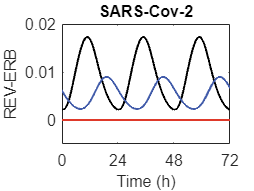


% Plot clock evolution of clock disruption
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
plot(tspan, y(:, 8, 4), 'k', 'LineWidth', 1.5);
plot(tspan, y_sa(:, 8, 4), 'Color', '#425CAA', 'LineWidth', 1.5);
plot(tspan, zeros(10001, 1), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([523 595]);
xticks(523:24:595);
ylim([-0.005 0.02]);
xticklabels({'0', '24', '48', '72'});
yticks([0 0.01 0.02]);
yticklabels({'0', '0.01', '0.02'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('REV-ERB','Fontsize',12, 'FontName', 'Arial');
title('SARS-Cov-2','Fontsize',12, 'FontName', 'Arial');
% legend('WT', 'Smaller Amp', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

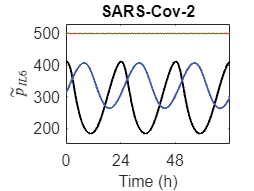


figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
plot(tspan, par_scg(6).*par_scg(15)./(par_scg(15)+y(:, 8, 4)), 'k', 'LineWidth', 1.5);
plot(tspan, par_scg(6).*par_scg(15)./(par_scg(15)+y_sa(:, 8, 4)), 'Color', '#425CAA', 'LineWidth', 1.5);
plot(tspan, par_scg(6).*par_scg(15)./(par_scg(15)+zeros(10001, 1)), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([523 595]);
xticks(523:24:595);
xticklabels({'0', '24', '48'});
ylim([150 530]);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('$\tilde{p}_{IL6}$', 'interpreter','latex', 'Fontsize',12, 'FontName', 'Arial');
title('SARS-Cov-2','Fontsize',12, 'FontName', 'Arial');
% legend('WT', 'Smaller Amp', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
hold off;

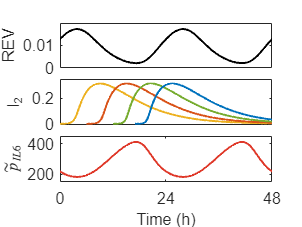

% Plot REV and phases
peak_idx_I2 = zeros(2, 1);    
for i = 1:2
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
% sz = 100;
% c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
% scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, color2, 'filled');
% scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, color2, '^', 'filled');
xlim([506 554]);
xticks([]);
yticks([0 0.01]);
ylabel('REV','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
plot(tspan((t_V_0*10+1):end), y((t_V_0*10+1):end, n_clock+3, 1), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_V_6*10+1):end), y((t_V_6*10+1):end, n_clock+3, 2), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_V_12*10+1):end), y((t_V_12*10+1):end, n_clock+3, 3), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_V_17*10+1):end), y((t_V_17*10+1):end, n_clock+3, 4), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([506 554]);
xticks([]);
ylim([-0.01 0.35]);
yticks([ 0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan, par_scg(6) .* par_scg(15) ./ (par_scg(15) + y(:, 8, 1)), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({'0', '24', '48'});
ylim([150 450]);
yticks([200 400]);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('$\tilde{p}_{IL6}$', 'interpreter', 'latex', 'Fontsize',12, 'FontName', 'Arial');
hold off;

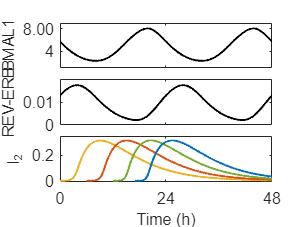

% Plot REV and phases
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);

subplot(3, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 1.5);
% sz = 100;
% c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
% scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, color2, 'filled');
% scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, color2, '^', 'filled');
xlim([506 554]);
xticks([506 530 554]);
xticklabels({});
ylim([1 9]);
yticks([4 8]);
yticklabels({'4', '8.00'});
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
% sz = 100;
% c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
% scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, color2, 'filled');
% scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, color2, '^', 'filled');
xlim([506 554]);
xticks([506 530 554]);
xticklabels({});
yticks([0 0.01]);
ylabel('REV-ERB','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan((t_V_0*10+1):end), y((t_V_0*10+1):end, n_clock+3, 1), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_V_6*10+1):end), y((t_V_6*10+1):end, n_clock+3, 2), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_V_12*10+1):end), y((t_V_12*10+1):end, n_clock+3, 3), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_V_17*10+1):end), y((t_V_17*10+1):end, n_clock+3, 4), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({'0', '24', '48'});
ylim([-0.01 0.35]);
yticks([ 0 0.2]);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

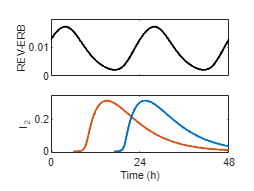

figure; hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
% set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
set(gcf, 'unit', 'centimeters', 'position', [10 5 6.73 5.05]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({});
yticks([0 0.01]);
ylabel('REV-ERB','Fontsize',8, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',8, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
% plot(tspan((t_V_0*10+1):end), y((t_V_0*10+1):end, n_clock+3, 1), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_V_6*10+1):end), y((t_V_6*10+1):end, n_clock+3, 2), 'Color', color4(2, :), 'LineWidth', 1.5);
% plot(tspan((t_V_12*10+1):end), y((t_V_12*10+1):end, n_clock+3, 3), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_V_17*10+1):end), y((t_V_17*10+1):end, n_clock+3, 4), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({'0', '24', '48'});
ylim([-0.01 0.35]);
yticks([ 0 0.2]);
xlabel('Time (h)','Fontsize',8, 'FontName', 'Arial');
ylabel('I_2','Fontsize',8, 'FontName', 'Arial');
hold off;

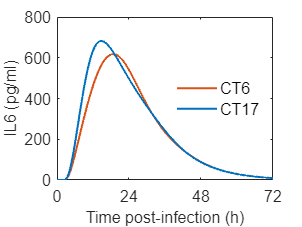

% plot diferent infection time of smaller amplitude
% Plot cytokines IL6 for smaller amplitude
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = [2 4]
    plot(tspan - t_V(i), y_sa(:, n_clock+5, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([0 72]);
xticks(0:24:72);
xlabel('Time post-infection (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
% legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

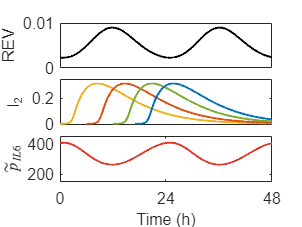

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan, y_sa(:, 8, 1), 'k', 'LineWidth', 1.5);
% sz = 100;
% c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
% scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, color2, 'filled');
% scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, color2, '^', 'filled');
xlim([506 554]);
xticks([]);
ylim([0 0.01]);
yticks([0 0.01]);
ylabel('REV','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
plot(tspan((t_V_0*10+1):end), y_sa((t_V_0*10+1):end, n_clock+3, 1), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_V_6*10+1):end), y_sa((t_V_6*10+1):end, n_clock+3, 2), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_V_12*10+1):end), y_sa((t_V_12*10+1):end, n_clock+3, 3), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_V_17*10+1):end), y_sa((t_V_17*10+1):end, n_clock+3, 4), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([506 554]);
xticks([]);
ylim([-0.01 0.35]);
yticks([ 0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan, par_scg(6) .* par_scg(15) ./ (par_scg(15) + y_sa(:, 8, 1)), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({'0', '24', '48'});
ylim([150 450]);
yticks([200 400]);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('$\tilde{p}_{IL6}$', 'interpreter', 'latex', 'Fontsize',12, 'FontName', 'Arial');
hold off;

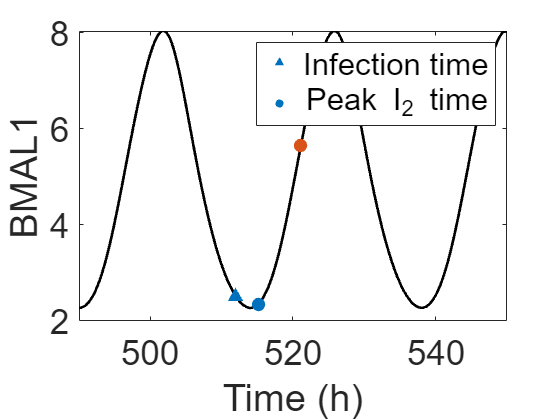


% Plot BMAL1/REV and phases of infection and peak time of I2
peak_idx_I2 = zeros(2, 1);    
for i = 1:2
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end
% Plot BMAL1 and phases
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 2);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 10, 1), y(t_V_17 .* 10 + 1, 10, 1)], sz, c, '^', 'filled');
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 10, 1),  sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('BMAL1');
legend('', 'Infection time', 'Peak I_2 time');
hold off;

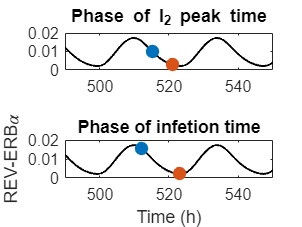

% Plot REV and phases
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(2, 1, 1); hold on; set(gca, 'Fontsize', 12); box on;
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, c, 'filled');
xlim([490 550]);
title('Phase of I_2 peak time');
hold off;

subplot(2, 1, 2); hold on; set(gca, 'Fontsize', 12); box on;
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('REV-ERB\alpha');
title('Phase of infetion time');
hold off;

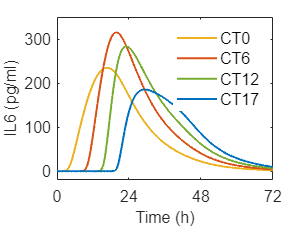

% change k_I - latent period
y_k_I = zeros(length(tspan), n_clock+7, 4);
k_I = par_scg(3);
par_scg(3) = 0.5;

[~, y_k_I(:, :, 1)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_0);
[~, y_k_I(:, :, 2)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y_k_I(:, :, 3)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_12);
[~, y_k_I(:, :, 4)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
y_k_I = real(y_k_I);

par_scg(3) = k_I;

% Plot cytokines IL6
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:4
    plot(tspan, y_k_I(:, n_clock+5, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([506 578]);
ylim([-20 350]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
% legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'northeast','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

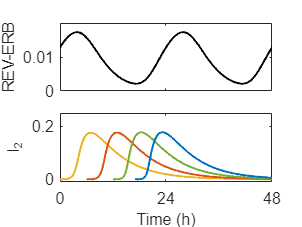


% Plot REV and phases
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan, y_k_I(:, 8, 1), 'k', 'LineWidth', 1.5);
% sz = 100;
% c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
% scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, color2, 'filled');
% scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, color2, '^', 'filled');
xlim([506 554]);
xticks([506 530 554]);
xticklabels({});
yticks([0 0.01]);
ylabel('REV-ERB','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
plot(tspan((t_V_0*10+1):end), y_k_I((t_V_0*10+1):end, n_clock+3, 1), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_V_6*10+1):end), y_k_I((t_V_6*10+1):end, n_clock+3, 2), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_V_12*10+1):end), y_k_I((t_V_12*10+1):end, n_clock+3, 3), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_V_17*10+1):end), y_k_I((t_V_17*10+1):end, n_clock+3, 4), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({'0', '24', '48'});
ylim([-0.01 0.25]);
yticks([ 0 0.2]);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

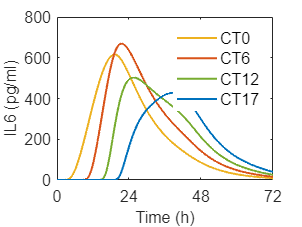

% change p_V
y_p_V = zeros(length(tspan), n_clock+7, 4);
p_V = par_scg(4);
par_scg(4) = 500000;

[~, y_p_V(:, :, 1)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_0);
[~, y_p_V(:, :, 2)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y_p_V(:, :, 3)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_12);
[~, y_p_V(:, :, 4)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
y_p_V = real(y_p_V);

par_scg(4) = p_V;

% Plot cytokines IL6
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:4
    plot(tspan, y_p_V(:, n_clock+5, i), 'Color', color4(i, :), 'LineWidth', 1.5);
end
xlim([506 578]);
% ylim([-20 350]);
xticks(506:24:578);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
% legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
legend('CT0', 'CT6', 'CT12', 'CT17', 'Box', 'off', 'Location', 'northeast','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

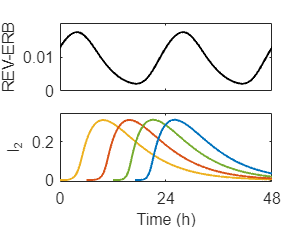


% Plot REV and phases
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan, y_p_V(:, 8, 1), 'k', 'LineWidth', 1.5);
% sz = 100;
% c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
% scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, color2, 'filled');
% scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, color2, '^', 'filled');
xlim([506 554]);
xticks([506 530 554]);
xticklabels({});
yticks([0 0.01]);
ylabel('REV-ERB','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
plot(tspan((t_V_0*10+1):end), y_p_V((t_V_0*10+1):end, n_clock+3, 1), 'Color', color4(1, :), 'LineWidth', 1.5);
plot(tspan((t_V_6*10+1):end), y_p_V((t_V_6*10+1):end, n_clock+3, 2), 'Color', color4(2, :), 'LineWidth', 1.5);
plot(tspan((t_V_12*10+1):end), y_p_V((t_V_12*10+1):end, n_clock+3, 3), 'Color', color4(3, :), 'LineWidth', 1.5);
plot(tspan((t_V_17*10+1):end), y_p_V((t_V_17*10+1):end, n_clock+3, 4), 'Color', color4(4, :), 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({'0', '24', '48'});
ylim([-0.01 0.35]);
yticks([ 0 0.2]);
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;